clear all;


genNum = 10000;
neuronNum = 15;
inputNum = 2;
% инициализация начальных весов
w = 10*rand(neuronNum,inputNum)-5;
u = 10*rand(neuronNum,1) - 5;

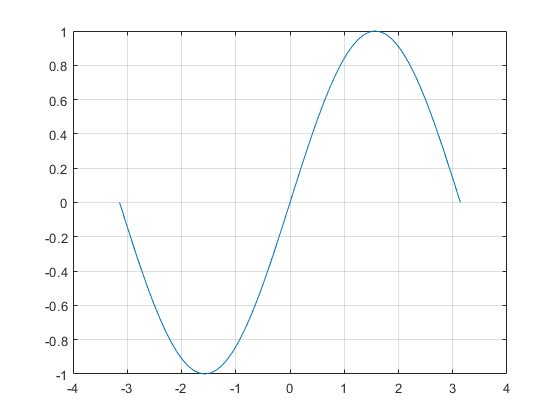

clf;
step = pi/30;
lb = -pi;
rb = pi;
XX = [lb:step:rb];
plot(XX, sin(XX))
grid on;

Инициализируем начальные нейроны

% bestResidual = inf
% bestW = zeros(neuronNum,inputNum);
% bestU = zeros(neuronNum);
% for k = 1:genNum
%     w = 2*rand(neuronNum,inputNum)-1;
%     u = 2*rand(neuronNum,1) - 1;
%     approxFunc = zeros(size(XX));
%     residual = 0;
%     for i = 1:numel(XX)
%         for j = 1:neuronNum
%             approxFunc(i) = approxFunc(i) + u(j)*neuron(XX(i), w(j,:));
%         end
%         residual = residual + (sin(XX(i)) - approxFunc(i))^2;
%     end
%     if residual < bestResidual
%         bestResidual = residual;
%         bestW = w;
%         bestU = u;
%     end
% end
% approxFunc = zeros(size(XX));
% clear residual
% w = bestW;
% u = bestU;
% for i = 1:numel(XX)
%     for j = 1:neuronNum
%         approxFunc(i) = approxFunc(i) + u(j)*neuron(XX(i), w(j,:));
%     end
% end
% hold on;
% plot(XX, approxFunc);

%просто комбинируем параметры чтобы почувствовать; далее эта переменная не
%используется
pars = [reshape(w,[1,neuronNum*inputNum]) u.'];
alpha = 0.5;
fitfunc = @(x)calcResidual(x, XX,neuronNum,inputNum, @neuron, alpha);

pars = ga(fitfunc, numel(pars));

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


pars2 = fminsearch(fitfunc,pars)

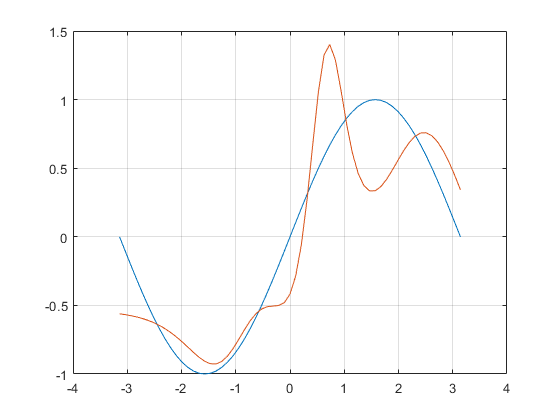

rpars = reshape(pars,[neuronNum,inputNum+1]);
w = rpars(:,1:end-1);
u = rpars(:,end);
approxFunc = zeros(size(XX));
for i = 1:numel(XX)
    for j = 1:neuronNum
        approxFunc(i) = approxFunc(i) + u(j)*neuron(XX(i), w(j,:));
    end
end
hold on;
plot(XX, approxFunc);